# Actividad 6 (Modelado de Energía Cinética)

### Robot Rotacional (2GDL)

### Daniel Castillo López

### A01737357

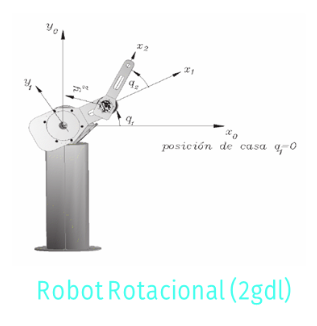


%Limpieza de pantalla
clear all
close all
clc

tic

Declaración de variables simbólicas

syms th1(t) th2(t)  t  %Angulos de cada articulación
syms th1p(t) th2p(t)     %Velocidades de cada articulación
syms th1pp(t) th2pp(t)   %Aceleraciones de cada articulación
syms m1 m2 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2   %Masas y matrices de Inercia
syms l1 l2 lc1 lc2  %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
  Q= [th1; th2];
  disp('Coordenadas generalizadas'); pretty (Q);

Coordenadas generalizadas
/ th1(t) \
|        |
\ th2(t) /



 
 %Creamos el vector de velocidades articulares
  Qp= [th1p; th2p];
  disp('Velocidades generalizadas');pretty (Qp);

Velocidades generalizadas
/ th1p(t) \
|         |
\ th2p(t) /



 %Creamos el vector de aceleraciones articulares
  Qpp= [th1pp; th2pp];
  disp('Aceleraciones generalizadas');pretty (Qpp);

Aceleraciones generalizadas
/ th1pp(t) \
|          |
\ th2pp(t) /




%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad (GDL)del robot,establecemos las 3
%articulaciones lo que corresponde a sus rotaciones
GDL= size(RP,2);
GDL_str= num2str(GDL);


## Cinematica directa

Se calcula las matrices de transformación homogenea utilizando en los parámetros de Denavit-Hartenberg.Permitiendo poder tener la posición y orientación del efecto final.Siendo fundamental para identificar el extremo del robot en base a los ángulos y desplazamientos de las articulaciones.

## Articulación 1 


%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1);0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1) 0;
           sin(th1)  cos(th1) 0;
           0            0     1];


### Articulación 2

%Posición de la articulación 2 respecto a 3
P(:,:,2)= [l2*cos(th2); l2*sin(th2);0];
%Matriz de rotación de la junta 3 respecto a 0
R(:,:,2)= [cos(th2) -sin(th2)  0;
           sin(th2)  cos(th2)  0;
           0            0      1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    disp(strcat('Matriz de Transformación local A', i_str));pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    T(:,:,i)= simplify(T(:,:,i));
   disp(strcat('Matriz de Transformación global T', i_str));pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación local A1
/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1
/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación local A2
/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2
/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




Se utilizan las matrices de transformación y el Jacobiano para calcular las velocidades lineales y angulares de cada eslabón en función de las velocidades articulares.Analizar cómo se mueve cada parte del robot y para controlar con precisión su trayectoria.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%CALCULAMOS LAS VELOCIDADES PARA CADA ESLABÓN%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 2  %%%%%%%%%%

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 2
V2=simplify (Jv_a*Qp);
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3');pretty(V2);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 3
/ - th1p(t) (l1 sin(th1(t)) + l2 #1) - l2 #1 th2p(t) \
|                                                    |
|  th1p(t) (l1 cos(th1(t)) + l2 #2) + l2 #2 th2p(t)  |
|                                                    |
\                          0                         /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




W2=simplify (Jw_a*Qp);
 disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');pretty(W2);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2
/         0         \
|                   |
|         0         |
|                   |
\ th1p(t) + th2p(t) /



%%%%%%%%%%  VELOCIDADES PARA ESLABÓN 2  %%%%%%%%%%

%Calculamos el jacobiano lineal y angular de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a1);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a1);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
%Obtenemos vectores de Velocidades Lineales y Angulares para el eslabón 1
 disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');pretty(V1);

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1
/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



W1=simplify (Jw_a1*Qp(1));
disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');pretty(W1);

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1
/    0    \
|         |
|    0    |
|         |
\ th1p(t) /



Se determina para cada eslabón considerando su masa, velocidad lineal y velocidad angular.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Energía Cinética
%%%%%%%%%%%%%%%%%%%%%%%%%%Omitimos la división de cada lc%%%%%%%%%%%%%%%
%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);%La función subs sustituye l1 por lc1 en 
 P12=subs(P(:,:,2), l2, lc2); %la expresión P(:,:,1)/2
%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales del efector final en cada eje
V2=V2(t);  
Vx= V2(1,1);
Vy= V2(2,1);
Vz= V2(3,1);

%Extraemos las velocidades angular del efector final en cada ángulo de Euler
W2=W2(t);
W_pitch= W2(1,1);
W_roll= W2(2,1);
W_yaw= W2(3,1);

## Calculamos la energía cinética para cada uno de los eslabones

Es la suma de las energías cinéticas de todos los eslabones, considerando tanto el movimiento lineal como el rotacional.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
K1= simplify (K1);
disp('Energía Cinética en el Eslabón 1');pretty (K1);

Energía Cinética en el Eslabón 1
              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1





%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
K2= simplify (K2);
disp('Energía Cinética en el Eslabón 2');pretty (K2);

Energía Cinética en el Eslabón 2
__                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___
m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)
---------------------------------------------------------------------------------------------------------------------------------------------------------------------- + Izz2 #1 | ------- + ------- | + ----------------------------------

%Energía cinética total
K_Total= simplify (K1+K2);
disp('Energía Cinética Total');pretty (K_Total);

Energía Cinética Total
          __                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___              ______           __                     2           2
Izz1 #5   m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)   #5 cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
------- + ------------------------------------------------------------------------------------

%Obtenemos las alturas respecto a la gravedad
h1= P01(2);
h2= P12(2); 

U1=m1*g*h1;
U2=m2*g*h2;

%Calculamos la energía potencial total
U_Total= U1 + U2;
disp('Energía Potencial Total'); pretty(U_Total);

Energía Potencial Total
g lc1 m1 sin(th1(t)) + g lc2 m2 sin(th2(t))



## Modelo de energía

%Obtenemos el Lagrangiano
% función que describe la diferencia entre la energía cinética y la energía potencial de un sistema físico. Se utiliza en la mecánica lagrangiana para formular las ecuaciones de movimiento de un sistema.
%L=K-U
Lagrangiano= simplify (K_Total-U_Total);
disp('Lagrangiano'); pretty (Lagrangiano);

Lagrangiano
          __                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___                                                            ______           __                     2           2
Izz1 #5   m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)                                                 #5 cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
------- + ---


%Modelo de Energía
H= simplify (K_Total+U_Total);
disp('Modelo de energía'); pretty (H)

Modelo de energía
          __                                                                                    _______          __       ______  __    _______         __       ______  ___               / _______   _______ \   __                                                                                    _______          __       ______  __    _______         __       ______  ___                                                            ______           __                     2           2
Izz1 #5   m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1) (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2)           | th1p(t)   th2p(t) |   m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1) (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2)                                                 #5 cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
-------

toc

Elapsed time is 9.922083 seconds.
